% Get all .wav files in the directory
files = dir(fullfile('Training_Data', '*.wav'));

% Extract numeric values from filenames for correct sorting
fileNames = {files.name};
numValues = zeros(length(fileNames), 1);

for i = 1:length(fileNames)
    numStr = regexp(fileNames{i}, '\d+', 'match'); % Extract numeric part
    numValues(i) = str2double(numStr{1}); % Convert to number
end

% Sort files numerically
[~, sortedIdx] = sort(numValues);
files = files(sortedIdx); % Reorder file structure

% Number of files
numFiles = length(files);
mfcc_data = cell(1, numFiles); %creates a cell array

for i = 1:numFiles
    % Construct full filename
    filename = fullfile(files(i).folder, files(i).name);
    
    % Read the audio file
    [signal, fs] = audioread(filename);
    
    % Convert stereo to mono (if necessary)
    if size(signal, 2) == 2
        signal = mean(signal, 2); % Take the average of both channels
    end

    %use cell array to save data
    mfcc_data{i} = our_mfcc(signal,fs);
 
    %loaded_data = load('mfcc_data.mat');
    %mfcc_data_loaded = loaded_data.mfcc_data;
 

    %builtin_mfcc = mfcc(signal,fs,"NumCoeffs",19);
    %disp(builtin_mfcc);


end

speaker1_mfcc = mfcc_data{1}

speaker1_mfcc =    -3.9552   -2.2057    0.9819    1.8596    1.5724    1.8867    1.6514    1.6807    1.3218    1.1797    1.1804    0.9324    1.0292    1.2184    1.3293    1.3326    1.8534    2.5787    2.7736    4.5805    4.9397    5.5535    5.9321    6.0730    6.3672    6.3035    6.5342    6.9060    6.8974    6.2586    6.1869    6.2108    6.4875    6.6390    6.8020    6.7903    6.8183    6.3134    6.6839    6.3441    6.2956    6.1584    5.3504    5.9333    6.0807    5.6050    6.0255    6.3418    6.1660    5.8373
    1.0541    3.0201    4.7106    3.0764    2.5880    2.4199    2.5571    2.4636    2.7317    2.7462    2.8750    3.0473    3.0432    2.8106    2.8297    2.5229    2.1247    1.3768    1.5314    0.4855    0.9869    1.0078    1.0654    1.0483    0.3731    0.2182    0.0812   -0.0284   -0.3718   -0.1587   -0.2662   -0.5033   -0.9465   -1.2051   -1.6397   -1.7487   -2.0628   -1.6320   -1.9102   -1.6144   -1.7114   -1.6899   -0.9482   -1.2125   -1.2674   -0.7147   -0.8793   -0.9172   

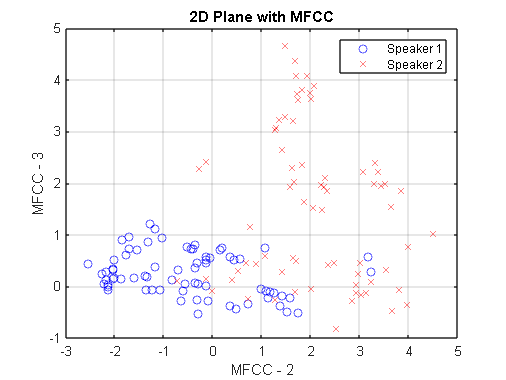

%% TEST 5
figure;
plot(mfcc_data{3}(2,:)',mfcc_data{3}(3,:)','o','Color','b');
hold on
grid on

plot(mfcc_data{10}(2,:),mfcc_data{10}(3,:)','x','Color','r');
legend('Speaker 1','Speaker 2');
title('2D Plane with MFCC');
xlabel('MFCC - 2');
ylabel('MFCC - 3');

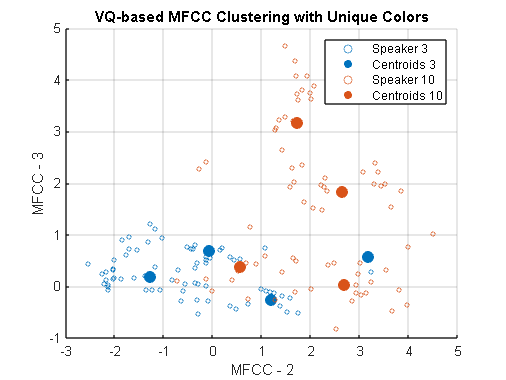

% Define parameters
M = 4;          % Desired number of centroids
epsilon = 0.01; % Splitting parameter
colors = lines(2); % Use 2 colors since we have 2 speakers

figure;
hold on;
grid on;

speakers = [3, 10]; % Speakers to plot

for idx = 1:length(speakers)
    i = speakers(idx); % Get actual speaker index
    trainingData = mfcc_data{i}; % Extract data
    codebook = lbg_algorithm2(trainingData', M); % Run LBG

    % Plot training data with distinct color
    scatter(trainingData(2,:)', trainingData(3,:)', 10, colors(idx,:), 'DisplayName', ['Speaker ' num2str(i)]); 

    % Plot centroids
    scatter(codebook(:,2), codebook(:,3), 80, colors(idx,:), 'filled', 'DisplayName', ['Centroids ' num2str(i)]); 
end

xlabel('MFCC - 2');
ylabel('MFCC - 3');
legend;
title('VQ-based MFCC Clustering with Unique Colors');
hold off;

Speaker Identify 

%{
% Load test audio
[test_signal, fs] = audioread('Training_Data.wav');

% Extract MFCCs for test speaker
test_mfcc = our_mfcc(test_signal, fs); 

% Load trained codebooks
load('trained_codebooks.mat');

% Identify speaker
identified_speaker = identify_speaker(test_mfcc, trained_codebooks);

fprintf('Predicted Speaker ID: %d\n', identified_speaker);
%}